# Simulated Sleep Spindle Recording Generator

% clear all
% tiledlayout(4,4)
% for Amplitude = [0.25,0.5,1,2]
% for F = [11 13 15 17]
for StopTime = [0.3/2 0.25 0.3 0.5]


## Signal Parameters

Total_Epochs = 100;
Epoch_size = 100; % seconds
fs = 2034;                    % Sampling frequency (samples per second)

## Real Spindle

Load Sample Real Spindle

%load mat
% aspindle = ;

## Artificial Spindle

Amplitude = 1;
% StopTime = 0.5;             % seconds
F = 15;                      % Sine wave frequency (hertz), should be between 11-17 Hz
NumberofSpindles_Epoch = 12;
filename = ['20221023_simulated_artificial_freq_' num2str(F) '_dur_' num2str(2*StopTime) '_Amp_' num2str(Amplitude)];


dt = 1/fs;                   % seconds per sample
t = (-StopTime:dt:StopTime-dt)';     % seconds
% data = sin(2*pi*F*t);


$$-x^2 \textrm{∙}\mathrm{s}\mathrm{i}\mathrm{n}\left(x\right)$$


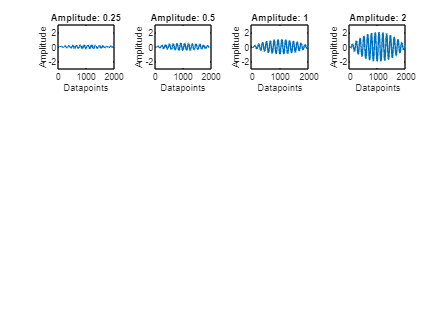

% figure
nexttile
aspindle = (-(t).^2+t(end)^2).*sin(2*pi*F*t); 
% aspindle = aspindle(round(0.4*length(aspindle)):round(0.6*length(aspindle)));
aspindle = Amplitude*(aspindle/max(aspindle));
plot(aspindle)
% title(['Amplitude: ' num2str(Amplitude)])
% title(['Frequency: ' num2str(F) ' Hz'])
title(['Duration: ' num2str(StopTime*2) ' seconds'])
ylabel('Amplitude')
xlabel('Datapoints')
xlim([0 2000])
ylim([-3 3])
end
disp('done')

## Load Raw Noisy Data without Sleep Spindles

### Load Raw mat file

data = load('raw_signal2.mat');
raw_signal2 = data.raw_signal2;

## Generate Simulated Signals

### Random Spindle Placement

Spindle_Placement = [];
Spindle_Answerkey = [];

for i = 1:Total_Epochs % Number of iterations

        % Random Spindle placement in Epoch
        total_placement_range = fs*Epoch_size-length(aspindle);

        SplindlePlacement_epoch = round(rand(1,NumberofSpindles_Epoch)*total_placement_range); % Default: 12 spindles place within a 100 second window of a 2034 Hz signal
        SplindlePlacement_epoch = sort(SplindlePlacement_epoch);
        
        for ii = 2:length(SplindlePlacement_epoch)
            while SplindlePlacement_epoch(ii)-SplindlePlacement_epoch(ii-1)<=length(aspindle)*2
                SplindlePlacement_epoch(ii) = SplindlePlacement_epoch(ii)+length(aspindle);
            end

            if SplindlePlacement_epoch(ii)>total_placement_range
                SplindlePlacement_epoch(ii)=[];
            end
        end




        spindles_epoch = zeros(1,fs*Epoch_size);

        for n = SplindlePlacement_epoch
            spindles_epoch(n:n+length(aspindle)-1) = aspindle*Amplitude*2500;
        end

        Spindle_Placement = [Spindle_Placement SplindlePlacement_epoch];
        Spindle_Answerkey = [Spindle_Answerkey spindles_epoch];   

        disp(['epoch ' num2str(i) '...'])
end

GroundTruth = abs(Spindle_Answerkey)>0;

for ii = 1:length(GroundTruth)-2
    if GroundTruth(ii) == 1 && GroundTruth(ii+2) == 1 && GroundTruth(ii+1) == 0
        GroundTruth(ii+1) = 1;
    end
end

GroundTruth = GroundTruth';

### Raw signal + Spindle

% Spindle_Answerkey = int32(Spindle_Answerkey);
% raw_signal = int32(raw_signal);
simulated_signal = raw_signal2*0.8 + Spindle_Answerkey*0.25;%rawsignal2*0.8 + Spindle_Answerkey*0.25;
simulated_signal = int32(simulated_signal);


###  Simulated Signal EDF

clear hdr
hdr = edfheader("EDF");
hdr.NumDataRecords = 1;
hdr.DataRecordDuration = seconds(length(simulated_signal)/fs);
hdr.NumSignals = 1;
hdr.SignalLabels = ["ChannelFake"];
hdr.PhysicalDimensions = repelem("mV",1);
hdr.PhysicalMin = min(simulated_signal);
hdr.PhysicalMax = max(simulated_signal);
hdr.DigitalMin = 1000*min(simulated_signal);
hdr.DigitalMax = 1000*max(simulated_signal);


edfwrite([filename '.edf'],hdr,simulated_signal*100)
save([filename '.mat'],"simulated_signal","-mat")

## Answer Key EDF

clear hdr
hdr = edfheader("EDF");
hdr.NumDataRecords = 1;
hdr.DataRecordDuration = seconds(length(Spindle_Answerkey)/fs);
hdr.NumSignals = 1;
hdr.SignalLabels = ["ChannelFake"];
hdr.PhysicalDimensions = repelem("mV",1);
hdr.PhysicalMin = min(Spindle_Answerkey);
hdr.PhysicalMax = max(Spindle_Answerkey);
hdr.DigitalMin = 1000*min(simulated_signal);
hdr.DigitalMax = 1000*max(simulated_signal);

% edfwrite([filename '_AnswerKey_signal.edf'],hdr,Spindle_Answerkey*1000)
save([filename '_AnswerKey_signal.mat'],"Spindle_Answerkey","-mat")
save([filename '_AnswerKey_GroundTruth.mat'],"GroundTruth","-mat")
% end

### RAW

% clear hdr
% hdr = edfheader("EDF");
% hdr.NumDataRecords = 1;
% hdr.DataRecordDuration = seconds(length(raw_signal)/fs);
% hdr.NumSignals = 1;
% hdr.SignalLabels = ["RawSignalNoSS"];
% hdr.PhysicalDimensions = repelem("mV",1);
% hdr.PhysicalMin = min(raw_signal);
% hdr.PhysicalMax = max(raw_signal);
% hdr.DigitalMin = 1000*min(simulated_signal);
% hdr.DigitalMax = 1000*max(simulated_signal);
% 
% edfwrite("raw_signal.edf",hdr,raw_signal*1000)
% save("raw_signal.mat","raw_signal","-mat")
disp('done')